## Set up the Import Options and import the data

clear; close all; clc
opts = spreadsheetImportOptions("NumVariables", 9);

% Specify sheet and range
opts.Sheet = "full_fact";
opts.DataRange = "B2:J37";

% Specify column names and types
opts.VariableNames = ["FM", "FD", "H", "AT", "tr", "tf_66","tf_50","tf_66_a","tf_50_a"];
opts.VariableTypes = ["categorical", "categorical", "categorical", "categorical", "double", "double", "double", "double", "double"];

% Specify variable properties
%opts = setvaropts(opts, ["Replicates", "D", "E", "VarName7"], "EmptyFieldRule", "auto");

% Import the data
data_full_fact = readtable("/Users/cyrilmonette/Desktop/EPFL 2018-2026/PhD - Mobots/ENG-606/project/RoboticFrameCharacterisation/full_fact.xlsx", opts, "UseExcel", false)

data_full_fact = 36×9 table
     FM        FD        H         AT         tr      tf_66     tf_50     tf_66_a    tf_50_a
    _____    ______    ______    _______    ______    ______    ______    _______    _______

    Water    Low       edge      Indoors    1.8433    5.3333       2.5      5.25        2.5 
    Water    Low       middle    Indoors    1.9167    8.8333    3.0833    10.583        3.5 
    Water    Medium    edge      Indoors    2.0833    4.0833    1.9167      4.25          2 
    Water    Medium    middle    Indoors    2.3333    9.6667    3.0833    10.083     3.3333 
    Water    High      edge      Indoors    2.4167    7.8333    2.3333    7.4167     2.3333 
    Water    H

clear opts % Clearing temporary variables

## Constant coeff model with three 3-level factors

response_ix = 5; % change here to switch response
mu=grpstats(data_full_fact{:,response_ix})

mu = 1.8521

temp_matrix = data_full_fact;
temp_matrix{:,response_ix} = data_full_fact{:,response_ix}-mu

temp_matrix = 36×9 table
     FM        FD        H         AT           tr        tf_66     tf_50     tf_66_a    tf_50_a
    _____    ______    ______    _______    __________    ______    ______    _______    _______

    Water    Low       edge      Indoors    -0.0087963    5.3333       2.5      5.25        2.5 
    Water    Low       middle    Indoors      0.064537    8.8333    3.0833    10.583        3.5 
    Water    Medium    edge      Indoors        0.2312    4.0833    1.9167      4.25          2 
    Water    Medium    middle    Indoors        0.4812    9.6667    3.0833    10.083     3.3333 
    Water    High      edge      Indoors       0.56454    7.8333    2.3333    7.4167  


% Main effects:
FMMeans=grpstats(temp_matrix(:,[1 response_ix]),{'FM'})

FMMeans = 3×3 table
              FM      GroupCount    mean_tr 
             _____    __________    ________

    Bees     Bees         12        -0.31741
    Honey    Honey        12        0.043704
    Water    Water        12          0.2737


FDMeans=grpstats(temp_matrix(:,[2 response_ix]),{'FD'});
FDMeans = FDMeans([2 3 1],:) % To re-order

FDMeans = 3×3 table
                FD      GroupCount     mean_tr 
              ______    __________    _________

    Low       Low           12         -0.17074
    Medium    Medium        12        -0.060463
    High      High          12           0.2312


HMeans = grpstats(temp_matrix(:,[3 response_ix]),{'H'})

HMeans = 2×3 table
                H       GroupCount    mean_tr 
              ______    __________    ________

    edge      edge          18        -0.12009
    middle    middle        18         0.12009


ATMeans = grpstats(temp_matrix(:,[4 response_ix]),{'AT'})

ATMeans = 2×3 table
                   AT       GroupCount     mean_tr 
                ________    __________    _________

    Indoors     Indoors         18         0.083611
    Outdoors    Outdoors        18        -0.083611



% Mixed effects:
% First we remove the main effects from temp_matrix
for i=1:3 % Removing FM
    temp_matrix{:,response_ix}=temp_matrix{:,response_ix}-FMMeans{i,3}*(temp_matrix{:,1}==FMMeans{i,1});
end
for i=1:3 % Removing FD
    temp_matrix{:,response_ix}=temp_matrix{:,response_ix}-FDMeans{i,3}*(temp_matrix{:,2}==FDMeans{i,1});
end
for i=1:2 % Removing H
    temp_matrix{:,response_ix}=temp_matrix{:,response_ix}-HMeans{i,3}*(temp_matrix{:,3}==HMeans{i,1});
end
for i=1:2 % Removing AT
    temp_matrix{:,response_ix}=temp_matrix{:,response_ix}-ATMeans{i,3}*(temp_matrix{:,4}==ATMeans{i,1});
end

% Then we compute the mixed effects

FM_FD = grpstats(temp_matrix(:,[1 2 response_ix]),{'FM','FD'})

FM_FD = 9×4 table
                     FM        FD      GroupCount     mean_tr 
                    _____    ______    __________    _________

    Bees_High       Bees     High          4          -0.22426
    Bees_Low        Bees     Low           4           0.19852
    Bees_Medium     Bees     Medium        4          0.025741
    Honey_High      Honey    High          4          0.018796
    Honey_Low       Honey    Low           4         -0.016759
    Honey_Medium    Honey    Medium        4         -0.002037
    Water_High      Water    High          4           0.20546
    Water_Low       Water    Low           4          -0.18176
    Water_Medium    Water    Medium        4         -0.023704

FM_H = grpstats(temp_matrix(:,[1 3 response_ix]),{'FM','H'});
FM_AT = grpstats(temp_matrix(:,[1 4 response_ix]),{'FM','AT'});
FD_H = grpstats(temp_matrix(:,[2 3 response_ix]),{'FD','H'});
FD_AT = grpstats(temp_matrix(:,[2 4 response_ix]),{'FD','AT'});
H_AT = grpstats(temp_matrix(:,[3 4 response_ix]),{'H','AT'});

% Then we remove the effect of mixed effects from temp_matrix
residuals_before_mixed = temp_matrix{:,response_ix}

residuals_before_mixed =    -0.0753
   -0.2421
    0.0544
    0.0643
    0.0961
    0.2726
    0.2558
    0.2656
   -0.0211
   -0.0113


for i=1:length(temp_matrix{:,response_ix}) % Removing FM_FD
    %First we find the row in FM_FD that matches the FM and FD of index i
    row = find( arrayfun(@(RIDX) FM_FD{RIDX,'FM'}== temp_matrix{i,'FM'} && FM_FD{RIDX,'FD'}==temp_matrix{i,'FD'}, 1:size(FM_FD,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FM_FD{row,4}; % column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FM_H
    %First we find the row in FM_H that matches the FM and H of index i
    row = find( arrayfun(@(RIDX) FM_H{RIDX,'FM'}== temp_matrix{i,'FM'} && FM_H{RIDX,'H'}==temp_matrix{i,'H'}, 1:size(FM_H,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FM_H{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FM_AT
    %First we find the row in FM_AT that matches the FM and AT of index i
    row = find( arrayfun(@(RIDX) FM_AT{RIDX,'FM'}== temp_matrix{i,'FM'} && FM_AT{RIDX,'AT'}==temp_matrix{i,'AT'}, 1:size(FM_AT,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FM_AT{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FD_H
    %First we find the row in FD_H that matches the FD and H of index i
    row = find( arrayfun(@(RIDX) FD_H{RIDX,'FD'}== temp_matrix{i,'FD'} && FD_H{RIDX,'H'}==temp_matrix{i,'H'}, 1:size(FD_H,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FD_H{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing FD_AT
    %First we find the row in FD_AT that matches the FD and AT of index i
    row = find( arrayfun(@(RIDX) FD_AT{RIDX,'FD'}== temp_matrix{i,'FD'} && FD_AT{RIDX,'AT'}==temp_matrix{i,'AT'}, 1:size(FD_AT,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-FD_AT{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
for i=1:length(temp_matrix{:,response_ix}) % Removing H_AT
    %First we find the row in H_AT that matches the H and AT of index i
    row = find( arrayfun(@(RIDX) H_AT{RIDX,'H'}== temp_matrix{i,'H'} && H_AT{RIDX,'AT'}==temp_matrix{i,'AT'}, 1:size(H_AT,1)) );
    temp_matrix{i,response_ix}=temp_matrix{i,response_ix}-H_AT{row,4}; %  column 4 is mean_tr (or mean/tf, etc.)
end
residuals_after_mixed = temp_matrix{:,response_ix}

residuals_after_mixed =     0.0438
   -0.1110
    0.0588
    0.0512
   -0.0593
    0.0165
   -0.0176
    0.0998
   -0.0784
    0.0095


## Dot Plot without mixed effects

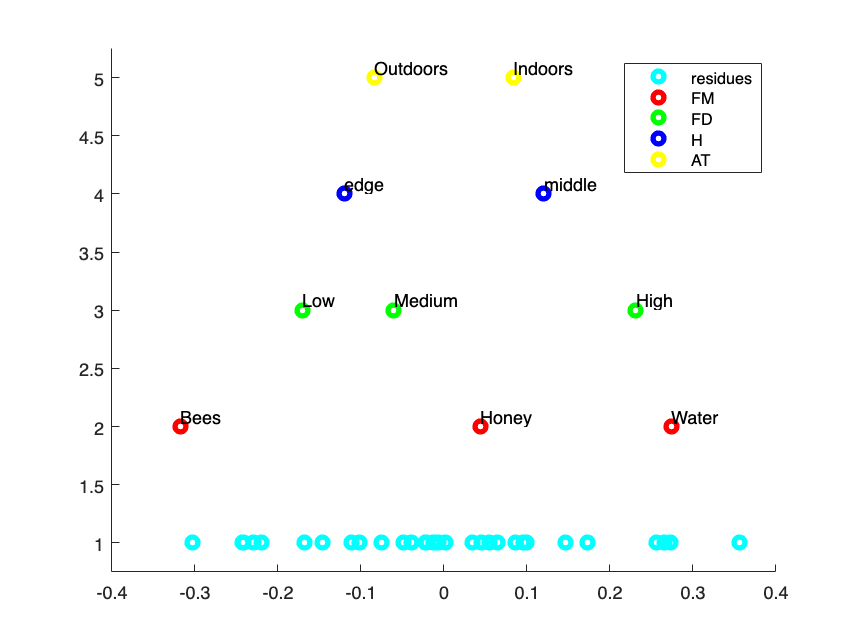

scatter(residuals_before_mixed,ones([1 height(residuals_before_mixed)]),"co","LineWidth",3)
hold on
scatter(FMMeans{:,3},2*ones([1 height(FMMeans)]),"ro","LineWidth",3)
scatter(FDMeans{:,3},3*ones([1 height(FDMeans)]),"go","LineWidth",3)
scatter(HMeans{:,3},4*ones([1 height(HMeans)]),"bo","LineWidth",3)
scatter(ATMeans{:,3},5*ones([1 height(ATMeans)]),"yo","LineWidth",3)
%scatter(res4,ones([1 length(res2)]),"co","LineWidth",3)
ylim([0.75 5.25])
%xlim([-80 80])
legend(["residues" "FM" "FD" "H" "AT"])
% Add labels
text(FMMeans{:,3}, 2*ones([1 height(FMMeans)]), FMMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(FDMeans{:,3}, 3*ones([1 height(FDMeans)]), FDMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(HMeans{:,3}, 4*ones([1 height(HMeans)]), HMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(ATMeans{:,3}, 5*ones([1 height(ATMeans)]), ATMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)

## Dot Plot with mixed effects

hold off

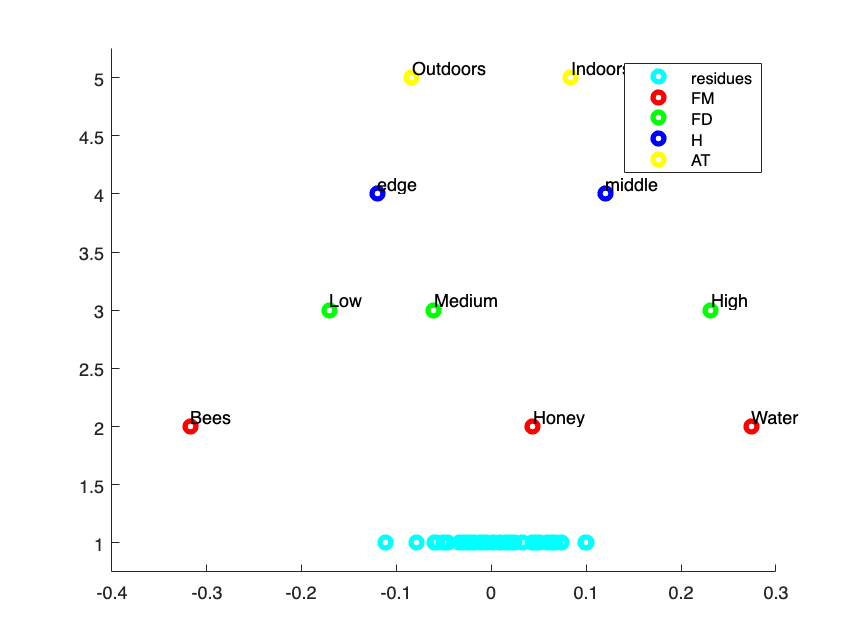

scatter(residuals_after_mixed,ones([1 height(residuals_after_mixed)]),"co","LineWidth",3)
hold on
scatter(FMMeans{:,3},2*ones([1 height(FMMeans)]),"ro","LineWidth",3)
scatter(FDMeans{:,3},3*ones([1 height(FDMeans)]),"go","LineWidth",3)
scatter(HMeans{:,3},4*ones([1 height(HMeans)]),"bo","LineWidth",3)
scatter(ATMeans{:,3},5*ones([1 height(ATMeans)]),"yo","LineWidth",3)
%scatter(res4,ones([1 length(res2)]),"co","LineWidth",3)
ylim([0.75 5.25])
%xlim([-80 80])
legend(["residues" "FM" "FD" "H" "AT"])
% Add labels
text(FMMeans{:,3}, 2*ones([1 height(FMMeans)]), FMMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(FDMeans{:,3}, 3*ones([1 height(FDMeans)]), FDMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(HMeans{:,3}, 4*ones([1 height(HMeans)]), HMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)
text(ATMeans{:,3}, 5*ones([1 height(ATMeans)]), ATMeans{:,1}, 'Vert','bottom', 'Horiz','left', 'FontSize',10)

## ANOVA

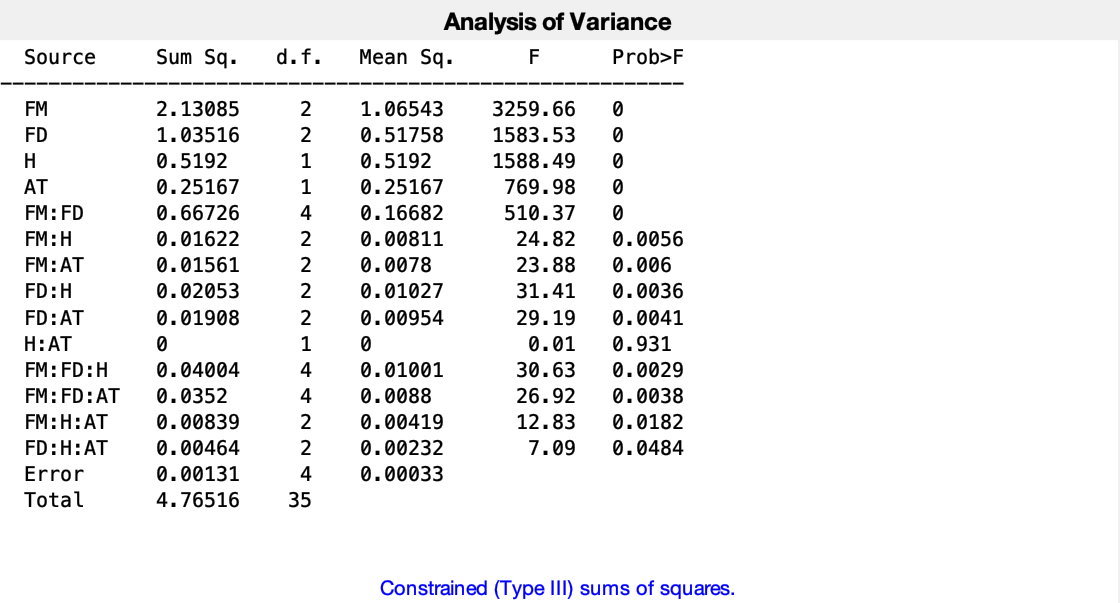

model_used=[1 0 0 0 ; 0 1 0 0 ; 0 0 1 0 ; 0 0 0 1; ... % Mains
           1 1 0 0 ; 1 0 1 0 ; 1 0 0 1 ; 0 1 1 0 ; 0 1 0 1 ; 0 0 1 1 ; ... % Two-ways
           1 1 1 0 ; 1 1 0 1 ; 1 0 1 1 ; 0 1 1 1 ;]; % Tree-ways

[p,tbl,stats] = anovan(data_full_fact{:,response_ix},{data_full_fact{:,1},data_full_fact{:,2},data_full_fact{:,3},data_full_fact{:,4}},'varnames',{'FM','FD','H','AT'},'model',model_used);

## Effect comparison

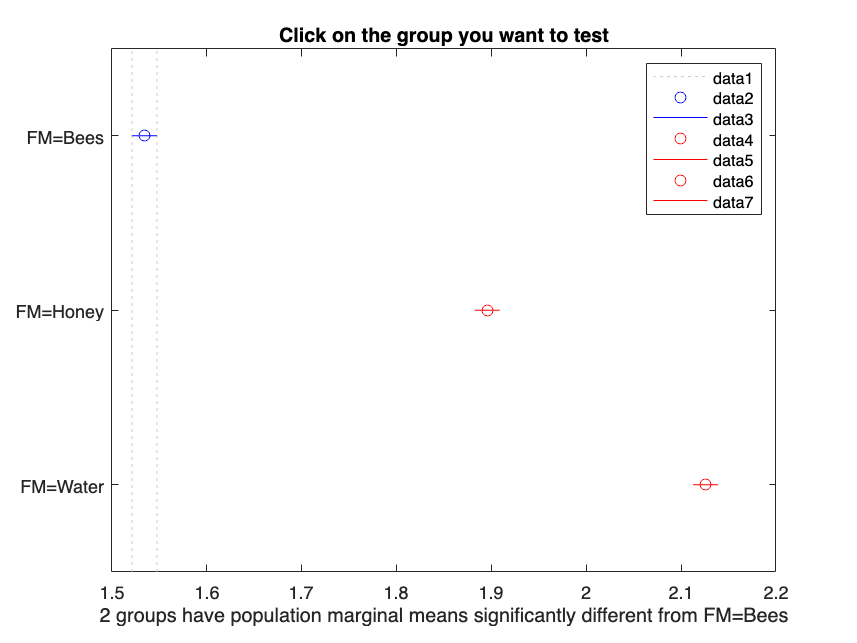

[comparison1,m1]=multcompare(stats,"Dimension",1,'Display','on');

Tcomparison=array2table(comparison1,"VariableNames",{'i','j','lim inf','delta','lim sup','p-value'});
disp(Tcomparison)

    i    j    lim inf      delta      lim sup      p-value  
    _    _    ________    ________    ________    __________

    1    2    -0.38742    -0.36111    -0.33481    1.5418e-06
    1    3    -0.61742    -0.59111    -0.56481    5.2836e-08
    2    3     -0.2563       -0.23     -0.2037    1.2914e-05



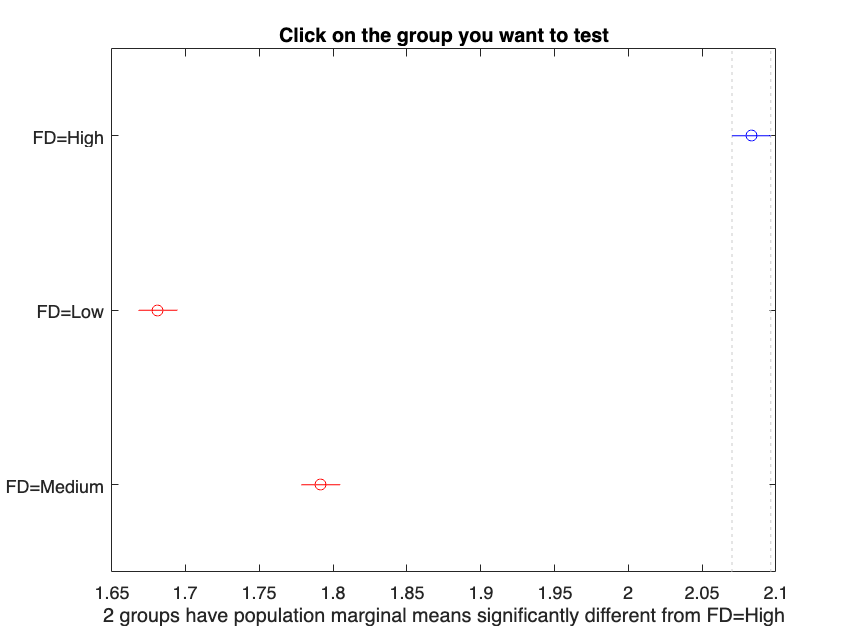


[comparison2,m2]=multcompare(stats,"Dimension",2,'Display','on');

Tcomparison=array2table(comparison2,"VariableNames",{'i','j','lim inf','delta','lim sup','p-value'});
disp(Tcomparison)

    i    j    lim inf      delta       lim sup      p-value  
    _    _    ________    ________    _________    __________

    1    2     0.37564     0.40194      0.42825    8.5035e-07
    1    3     0.26536     0.29167      0.31797     4.461e-06
    2    3    -0.13658    -0.11028    -0.083973    0.00025944



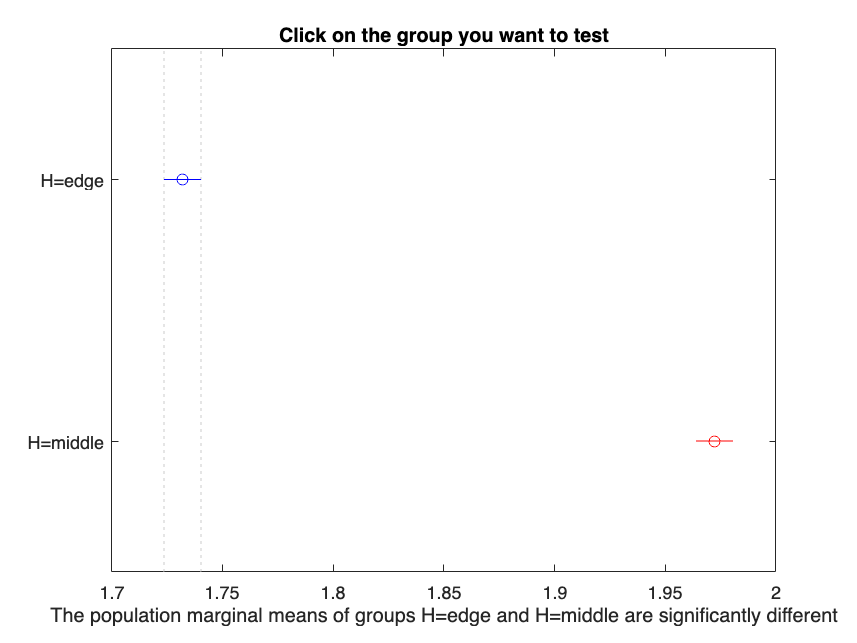


[comparison3,m3]=multcompare(stats,"Dimension",3,'Display','on');

Tcomparison=array2table(comparison3,"VariableNames",{'i','j','lim inf','delta','lim sup','p-value'});
disp(Tcomparison)

    i    j    lim inf      delta      lim sup      p-value  
    _    _    ________    ________    ________    __________

    1    2    -0.25692    -0.24019    -0.22345    1.7825e-06



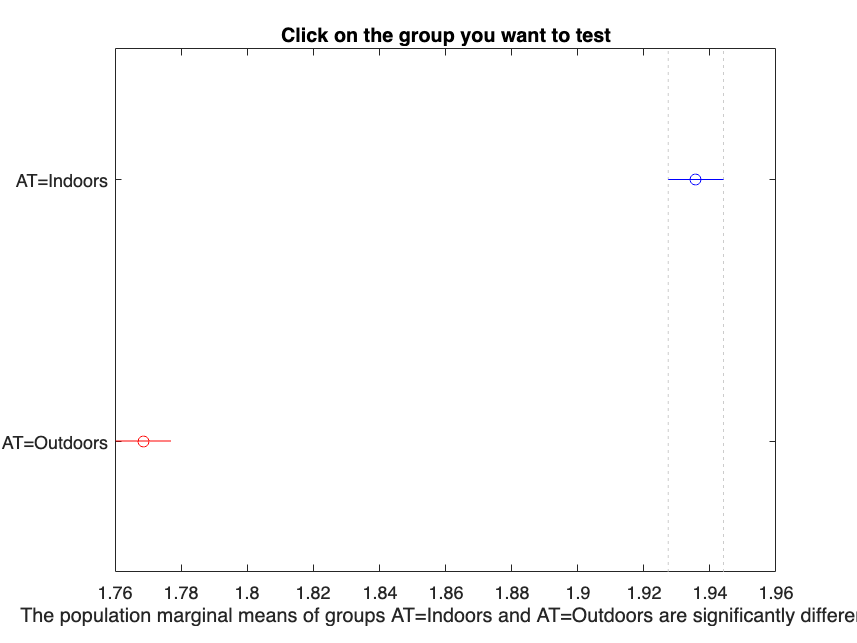


[comparison4,m4]=multcompare(stats,"Dimension",4,'Display','on');

Tcomparison=array2table(comparison3,"VariableNames",{'i','j','lim inf','delta','lim sup','p-value'});
disp(Tcomparison)

    i    j    lim inf      delta      lim sup      p-value  
    _    _    ________    ________    ________    __________

    1    2    -0.25692    -0.24019    -0.22345    1.7825e-06

